img = im2gray(imread("00001.jpg"))

img = 227×227 uint8 matrix
   133   134   137   138   138   137   135   134   141   140   137   136   135   137   138   140   138   135   132   132   134   136   134   132   135   135   135   135   135   135   135   135   136   137   138   139   138   137   135   134   135   135   137   139   140   138   134   131   140   140
   135   136   137   138   138   137   136   136   139   138   137   137   137   139   142   143   138   136   133   133   135   136   135   133   135   135   135   135   135   135   135   135   135   136   137   138   137   136   134   133   136   135   135   136   137   137   134   132   136   136
   139   138   138   137   137   137   138   138   140   139   138   138   138   140   142   143   138   136   134   134   135   136   135   134   136   136   136   136   136   136   136   136   134   135   136   137   136   135   133   132   138   136   133   133   134   135   135   134   136   136
   142   140   138   137   137   138   139   140   141   140   139   1


BW = imbinarize(img)

BW = 227×227 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1 

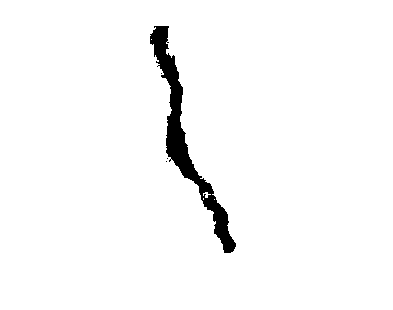

imshow(BW)


maskedImg = img

maskedImg = 227×227 uint8 matrix
   133   134   137   138   138   137   135   134   141   140   137   136   135   137   138   140   138   135   132   132   134   136   134   132   135   135   135   135   135   135   135   135   136   137   138   139   138   137   135   134   135   135   137   139   140   138   134   131   140   140
   135   136   137   138   138   137   136   136   139   138   137   137   137   139   142   143   138   136   133   133   135   136   135   133   135   135   135   135   135   135   135   135   135   136   137   138   137   136   134   133   136   135   135   136   137   137   134   132   136   136
   139   138   138   137   137   137   138   138   140   139   138   138   138   140   142   143   138   136   134   134   135   136   135   134   136   136   136   136   136   136   136   136   134   135   136   137   136   135   133   132   138   136   133   133   134   135   135   134   136   136
   142   140   138   137   137   138   139   140   141   140   1


maskedImg(BW) = 0

maskedImg = 227×227 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

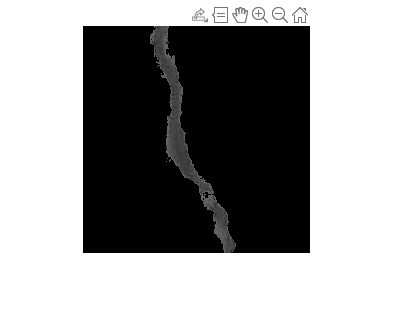


imshow(maskedImg)

armXray = imread("armxray.png")

armXray = 1000×1000 uint8 matrix
    4    4    3    2    3    3    3    1    2    3    5    5    3    4    5    5    6    6    6    6    7    7    6    6    6    6    7    7    6    7    9    9    7    6    7    8    8    5    9   11   10    9    9    9   10   10   11   11   11    9
    3    3    3    3    3    3    3    1    0    2    3    5    2    3    4    5    6    6    6    7    7    7    6    6    6    6    7    6    6    6    6    7    7    7    8   10    9    5   10   10   10   10   10   10   11   11   11   11   11    9
    3    3    3    3    3    3    2    2    1    2    3    4    2    2    3    4    5    8    7    6    7    6    6    6    7    7    7    6    6    6    5    7    6    6    9   11   11    9    6   10   10   10   10   10   10   11   10   10   10    9
    3    3    3    2    4    3    3    3    3    3    4    3    3    2    3    7    8    7    6    6    6    7    5    6    7    7    7    6    6    8    5    6    6    5    8   10   11    8    7    9    9   10   1

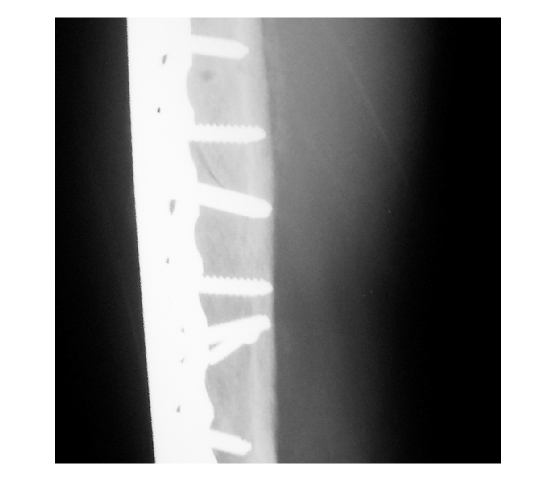

imshow(armXray)


thresValues = multithresh(armXray, 3)

thresValues = 1×3 uint8 row vector
    54   147   223


labels = imquantize(armXray, thresValues)

labels =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1    

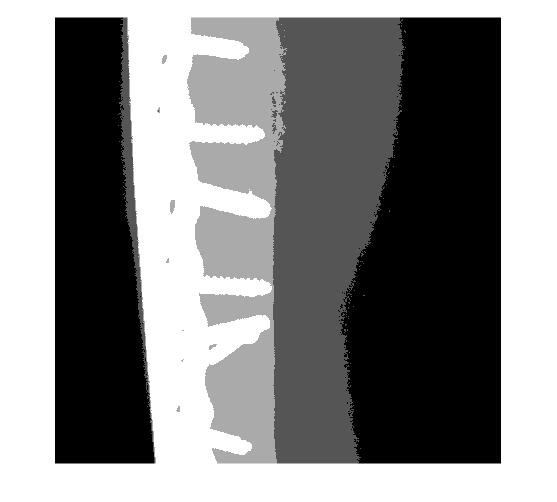


imshow(labels, [])